clear all;
close all;
clc;


id = fopen('D:\Studying\MCL-JCI\MCL-JCI\JND_samples_myspcae\JND_image_01.txt')
c = textscan(id, '%s %d %d %d %*[^\n]');
celldisp(c(3))

clear all;
close all;
clc;

id_name = ['D:\Studying\MCL-JCI\MCL-JCI\JND_samples_myspcae\', 'JND_image_01' '.txt']
c = textscan(id_name, '%s %d %d %d %*[^\n]');
celldisp(c(2))

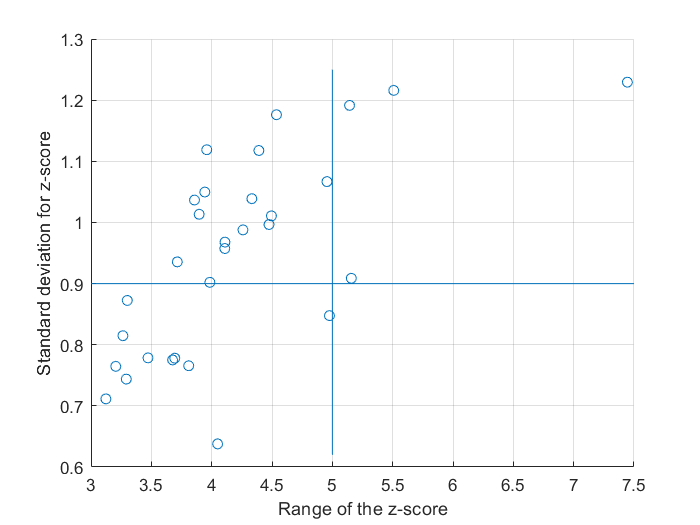

clear all;
close all;
clc;

load JND_first.mat;
load JND_second.mat;
load JND_third.mat;

% Mean of the JND samples for all images.
% mu is the matrix of length 50, since there are 50 imgaes in total.
mu = zeros(50,1);
for i = 1:50
    mu(i) = mean(JND_result_first(i,:));
end
std_for_all_images = std(JND_result_first');

% Compute the z-score of each tester for each image.
z_score_array = zeros(30,50);
z_score_temp = zeros(1,50);
% Loop for tester.
for x = 1:30
%     Loop for images.
    for y = 1:50
       z_score_temp(y) = (JND_result_first(y,x) - mu(y)) / std_for_all_images(y);
    end
    z_score_array(x,:) = z_score_temp;
end

z_score_array = z_score_array';
% std_for_z_score = zeros(1,30)
std_for_z_score = std(z_score_array);
max_for_z_score = max(z_score_array);
min_for_z_score = min(z_score_array);
range_maxAndmin_z_score = max_for_z_score - min_for_z_score;
scatter(range_maxAndmin_z_score, std_for_z_score);
xlabel('Range of the z-score');
ylabel('Standard deviation for z-score');
grid on;
hold on;
x = [5 5];
y = [1.25 0.62];
line(x,y);
hold on
x = [3 5.25];
y = [0.9 0.9];
xlim = get(gca,'XLim');
m = (y(2)-y(1))/(x(2)-x(1));
n = y(2) - x(2)*m;
y1 = m*xlim(1) + n;
y2 = m*xlim(2) + n;
line([xlim(1) xlim(2)],[y1 y2])